# Toolbar

The `wt.Toolbar` widget enables you to construct a lightweight toolstrip or toolbar for controlling your app. You can create multiple sections in horizontal format with vertical subsections as desired. The Toolbar methods enable you to easily add push buttons or state buttons. You may add other controls to the toolbar manually.

## Initial Creation

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 660 120]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

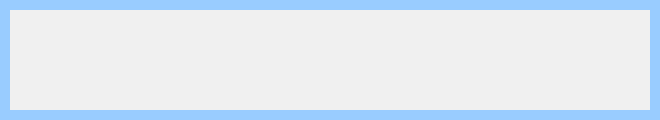

toolbarWidget1 = wt.Toolbar(gridObj);

Add a callback to the entire Toolbar widget. All button controls added using the Toolbar methods will trigger this callback. You may also opt to set a `ButtonPushedFcn` callback for each *Section* you create, if you prefer to have a separate callback per section. 

toolbarWidget1.ButtonPushedFcn = @(src,evt)disp(evt)

toolbarWidget1 =   Toolbar with properties:

    ButtonPushedFcn: @(src,evt)disp(evt)

            Section: [0×1 HorizontalSection]
       DividerColor: [0.9400 0.9400 0.9400]
         TitleColor: [0.5000 0.5000 0.5000]

           Position: [11 11 640 100]
              Units: 'pixels'

  Show all properties


## Horizontal Section with Push Buttons

Add a horizontal section with basic  push buttons:

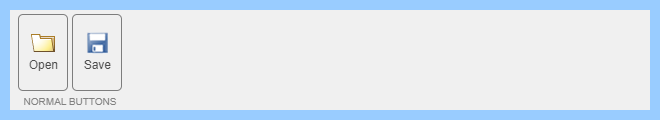

toolbarWidget1 =   Toolbar with properties:

    ButtonPushedFcn: @(src,evt)disp(evt)

            Section: [1×1 HorizontalSection]
       DividerColor: [0.9400 0.9400 0.9400]
         TitleColor: [0.5000 0.5000 0.5000]

           Position: [11 11 640 100]
              Units: 'pixels'

  Show all properties


section1 = wt.toolbar.HorizontalSection();
section1.Title = "NORMAL BUTTONS";
section1.addButton("open_24.png", "Open");
section1.addButton("save_24.png", "Save");

toolbarWidget1.Section = section1

## Horizontal Section with State Buttons

Add another horizontal section, this one containing state buttons:

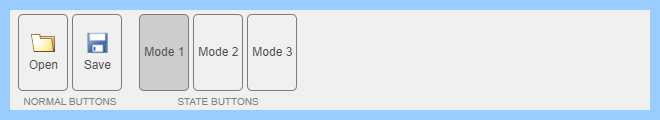

section2 = wt.toolbar.HorizontalSection();
section2.Title = "STATE BUTTONS";
stateButton1 = section2.addStateButton("","Mode 1");
stateButton2 = section2.addStateButton("","Mode 2");
stateButton3 = section2.addStateButton("","Mode 3");

toolbarWidget1.Section = [section1; section2];

Set the state of the buttons:

stateButton1.Value = true;
stateButton2.Value = false;
stateButton3.Value = false;

## Horizontal Section Containing Vertical Subsection with Mixed Content

Create a horizontal section:

section3 = wt.toolbar.HorizontalSection();
section3.Title = "MIXED HORIZONTAL / VERTICAL";
section3.addButton("left_24.png","");
section3.addButton("right_24.png","");

Add a vertical subsection to the horizontal section:

section3v1 = section3.addVerticalSection();

Add buttons to the vertical subsection:

section3v1.addButton("play_24.png","Play");
section3v1.addButton("stop_24.png","Stop");

Add a manual component to the vertical subsection:

sliderObj = uislider("Parent",[]);
section3v1.Component(end+1) = sliderObj;

Components added in this way require setting their own callbacks:

sliderObj.ValueChangedFcn = @(src,evt)disp(evt);

Add one final button to complete the horizontal section:

section3.addButton("pause_24.png","Pause");

Attach the horizontal section to the toolbar:

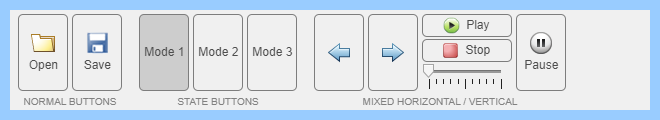

toolbarWidget1.Section = [section1; section2; section3];

## Final Horizontal Section

Add one additional horizontal section to complete the toolbar:

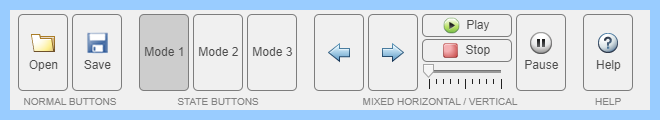

section4 = wt.toolbar.HorizontalSection();
section4.Title = "HELP";
section4.addButton('help_24.png','Help');

toolbarWidget1.Section = [section1; section2; section3; section4];

*Copyright 2020-2025 The MathWorks, Inc.*